# Remote read of NWB files

It is possible to read an NWB file (or any HDF5 file) in MATLAB directly from several different kinds of remote locations, including AWS, Azure Blob Storage and HDFS. This tutorial will walk you through specifically loading a MATLAB file from AWS S3, which is the storage used by the DANDI archive. See [MATLAB documentation](https://www.mathworks.com/help/matlab/ref/h5read.html) for more general information.

To read an NWB file file from an s3 store, first you need to figure out the s3 path of that resource. The easiest way to do this is to use the DANDI web client. 

- (skip if on DANDI Hub) Make sure you do not have a file `~/.aws/credentials`. If you do, rename it to something else. On Windows this file would be somewhere like `C:/Users/username/.aws/credentials`.

- Find and select a dandiset you want on the [DANDI Archive](https://dandiarchive.org/dandiset), then click 

- Navigate to the NWB file of interest and click  

- Find the second entry of "contentURL"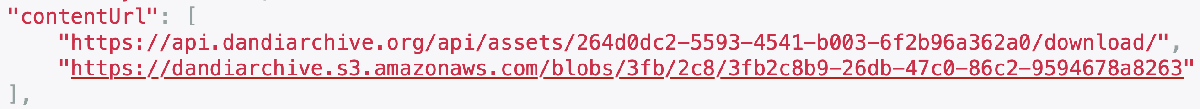

- In your MATLAB session, take the end of that url (the blob id) and add it to this expression: `s3 = 's3://dandiarchive/blobs/<blob_id>'`. In this case, you would have:

s3 = "s3://dandiarchive/blobs/3fb/2c8/3fb2c8b9-26db-47c0-86c2-9594678a8263";  % 380KiB file from dandiset 001199

- Read from that s3 path directly with:

nwbfile = nwbRead(s3);

That's it! MATLAB will automatically detect that this is an S3 path instead of a local filepath and will set up a remote read interface for that NWB file. This approach works on any computer with a fairly recent version of MATLAB and an internet connection. It works particularly well on the [DANDI Hub](http://hub.dandiarchive.org), which has a very fast connection to the DANDI S3 store and which provides a MATLAB environment for free provided you have a license.

## Note: MATLAB vs. Python remote read

Python also allows you to remotely read a file, and has several advantages over MATLAB. Reading in Python is faster. On DANDI Hub, for MATLAB, reading the file takes about 51 seconds, while the analogous operation takes less than a second in Python. Python also allows you to create a local cache so you are not repeatedly requesting the same data, which can further speed up data access. Overall, we recommend remote reading using Python instead of MATLAB.